clc;
clear;
close all;

% Load Smooth Trajectory
smooth_trajectory = load('smooth_trajectory.mat');
sample_time = mean(diff(smooth_trajectory.t));

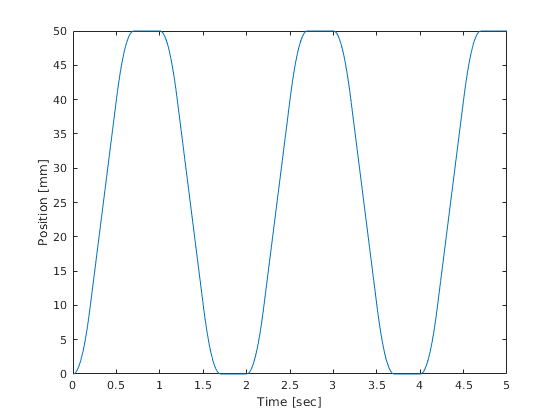

% Plot Trajectory
figure('Name', 'Smooth Trajectory');
title('Smooth Trajectory');

plot(smooth_trajectory.t, smooth_trajectory.xr);
xlabel('Time [sec]'); 
ylabel('Position [mm]');

% Run PID Simulink

% PID Gains
k_p = 1.776525791;
k_i = 102.89;
k_d = 0.0597;

% Fake Model Parameters (velocity model)
k_v = 50; % dc gain
tau_s = 0.04; % basically settling time

sim_output = sim('pid_model.slx')

sim_output =   Simulink.SimulationOutput:

                 simout: [1x1 struct] 
                   tout: [5060x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


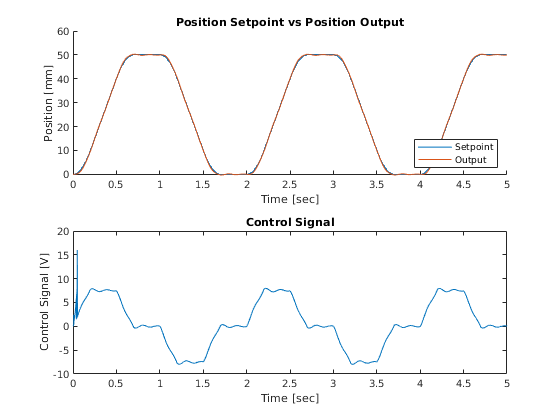

% Plot Outputs
figure('Name', 'Sim Output');

subplot(2, 1, 1)
hold on;
plot(sim_output.simout.position_setpoint);
plot(sim_output.simout.position_output);
title('Position Setpoint vs Position Output');

legend('Setpoint', 'Output', 'Location','southeast')
xlabel('Time [sec]'); 
ylabel('Position [mm]');

subplot(2, 1, 2)
plot(sim_output.simout.control);
title('Control Signal');
xlabel('Time [sec]'); 
ylabel('Control Signal [V]')

position_setpoints = sim_output.simout.position_setpoint.Data

position_setpoints =          0
    0.0002
    0.0010
    0.0022
    0.0040
    0.0062
    0.0090
    0.0122
    0.0160
    0.0202


position_outputs = sim_output.simout.position_output.Data

position_outputs =          0
         0
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0003
    0.0005


controls = sim_output.simout.control.Data

controls =          0
    0.0154
    0.0465
    0.0783
    0.1108
    0.1440
    0.1778
    0.2124
    0.2477
    2.3947
